## Deconvolución de imágenes 

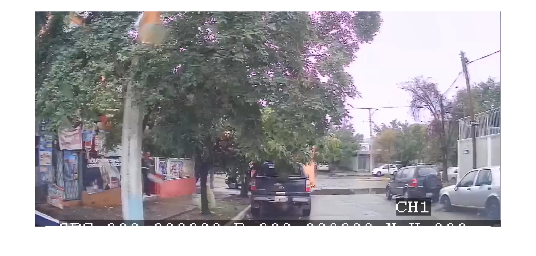

imagen = imread("C:\Users\HOME\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Desktop\Proyecto metodos\dashcam_1.png");
imshow(imagen)

Deconvolución ciega

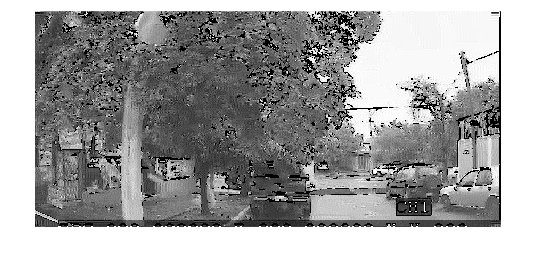

img_bw = rgb2gray(imagen);

initial_psf = ones(3);
[J P] = deconvblind(img_bw, initial_psf, 300);

img_edge = edge(img_bw,'sobel', 0.10);
se = strel('disk', 2);
img_edge = 1-double(imdilate(img_edge, se));



[J2, P2] = deconvblind (img_bw, P,500,[], img_edge);



imshow(J2)

P2

P2 =    0.116675490891897   0.117742496416295   0.110678877654101
   0.119456998517686   0.146485815275910   0.115957663164952
   0.090383527784041   0.099295615097275   0.083323515197843


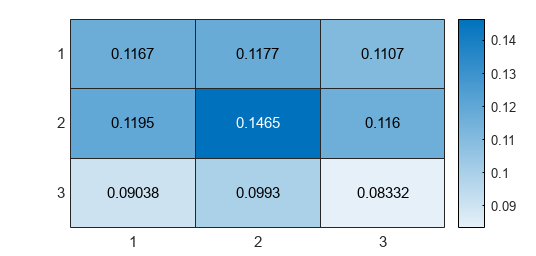

heatmap(P2), 

surface